close all
clear
clc

看图，用结构数组描述所有8个子图的标题、零点和极点

data = struct( ...
    'title', {'(a)','(b)','(c)','(d)','(e)','(f)','(g)','(h)'}, ...
    'zeros',{[],[0],[0;0],[-0.5],[0],[1.2j;-1.2j],[0;0],[1.2j;-1.2j]},...
    'poles',{[-2;-1],[-2;-1],[-2;-1],[-2;-1],[-1+1j;-1-1j],[-1+1j;-1-1j],[-1+1j;-1-1j],[1j;-1j]});

生成频点

omega = [0.01:0.01:6]';

循环逐一绘图

figure;
for id = 1:8

将零、极点转换成传递函数的分子、分母多项式系数

    [b,a] = zp2tf(data(id).zeros,data(id).poles,1);

在指定频点上计算频率响应

    H = freqs(b,a,omega);

绘制幅频响应，显示标题

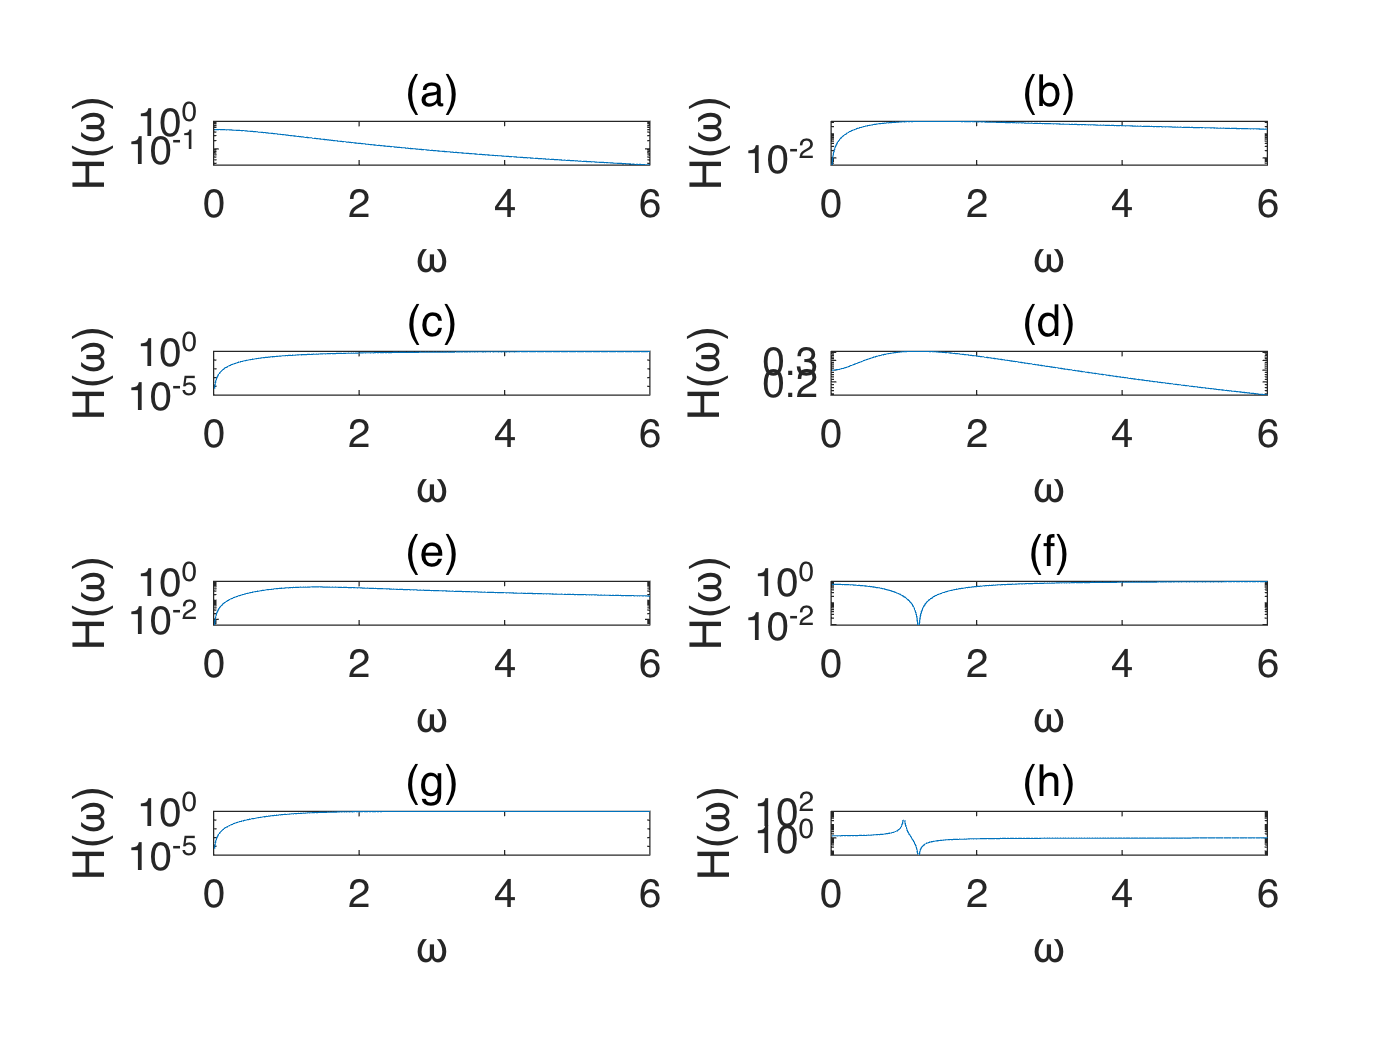

    subplot(4,2,id);
    plot(omega,abs(H));
    set(gca,'YScale','log','FontSize',16);
    title(data(id).title);
    xlabel('\omega');
    ylabel('H(\omega)');
end